# Math 244: MATLAB Assignment 7

### Name: Kym Derriman

### RUID: 033004091

### Date: December 2, 2024

clear;
clc;

## 1. 

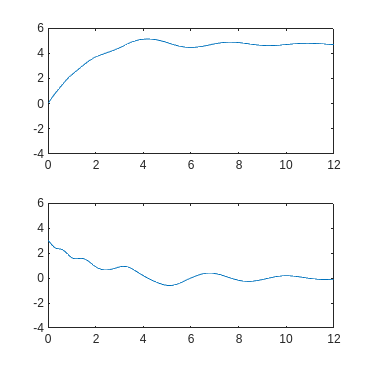

f = @(x,y) y;
g = @(x,y) -sin(4*x) - 0.5*y;
F = @(t, x) [f(x(1), x(2)); g(x(1), x(2))];

[t,x] = ode45(F, [0, 12], [0;3]);

xSol1 = x(:, 1);
ySol1 = x(:, 2);

figure();
set(gcf, 'Position', [100, 100, 800, 800]);
subplot(2,1,1)
plot(t, xSol1);
axis([0, 12, -4, 6]);

subplot(2, 1, 2)
plot(t, ySol1);
axis([0, 12, -4, 6]);

x(t) goes to 4.6 as t goes to infinity; y(t) goes to -0.1 as t approaches infinity.

## 2.

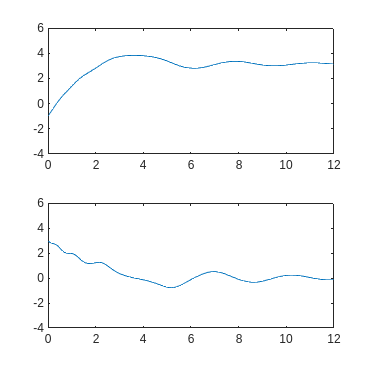

f = @(x,y) y;
g = @(x,y) -sin(4*x) - 0.5*y;
F = @(t, x) [f(x(1), x(2)); g(x(1), x(2))];

[t,x] = ode45(F, [0, 12], [-1;3]);

xSol2 = x(:, 1);
ySol2 = x(:, 2);

figure();
set(gcf, 'Position', [100, 100, 800, 800]);
subplot(2,1,1)
plot(t, xSol2);
axis([0, 12, -4, 6]);

subplot(2, 1, 2)
plot(t, ySol2);
axis([0, 12, -4, 6]);

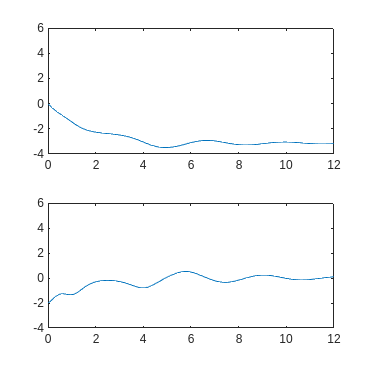

[t,x] = ode45(F, [0, 12], [0;-2]);

xSol3 = x(:, 1);
ySol3 = x(:, 2);

figure();
set(gcf, 'Position', [100, 100, 800, 800]);
subplot(2,1,1)
plot(t, xSol3);
axis([0, 12, -4, 6]);

subplot(2, 1, 2)
plot(t, ySol3);
axis([0, 12, -4, 6]);

For initial condition (-1,3), y(t) approaches -0.15 and x(t) approaches 3.15.

For (0,-2), x(t) approaches -3.2 and y(t) approaches 0.

Based on these, it seems like the solutions depend on both initial conditions and are not independent.

## 3.

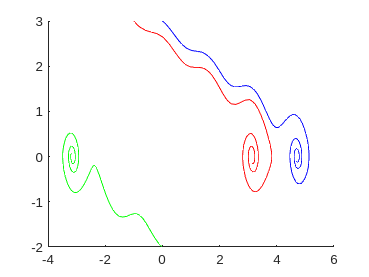

figure();
set(gcf, 'Position', [100, 100, 800, 600]);
hold on;
plot(xSol1, ySol1, 'b');
plot(xSol2, ySol2, 'r');
plot(xSol3, ySol3, 'g');
hold off;

## 4.

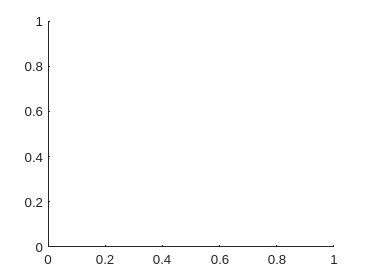

figure();
set(gcf, 'Position', [100, 100, 800, 600]);
hold on;

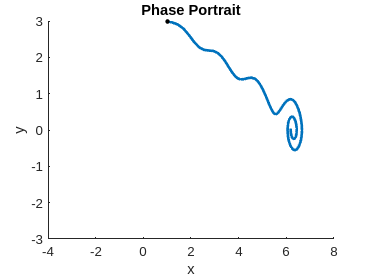

phasePortrait244(f, g, -4, 8, -3, 3, 0, 10, 1, 3);

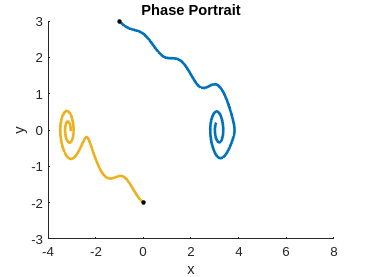

phasePortrait244(f, g, -4, 8, -3, 3, 0, 10, [-1,0], [3,-2]);
hold off;

## 5.

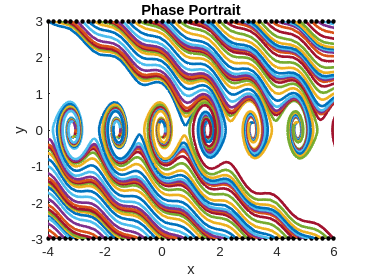

figure();
set(gcf, 'Position', [100, 100, 800, 600]);
phasePortrait244(f, g, -4, 6, -3, 3, 0, 10, [-4:0.2:6, -4:0.2:6], [3*ones(1, 51), -3*ones(1, 51)]);

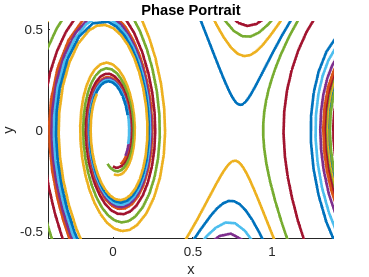


figure();
set(gcf, 'Position', [100, 100, 800, 600]);
phasePortrait244(f, g, -4, 6, -3, 3, 0, 10, [-4:0.2:6, -4:0.2:6], [3*ones(1, 51), -3*ones(1, 51)]);
xlim([-0.41 1.39])
ylim([-0.54 0.54])

After completing the lab, I went back and zoomed in (made another plot with smaller limits) on this phase portrait. This second plot really shows the different behavior at the points discussed in step 7. Namely, you can see, side by side, the converging behavior around (0,0) and the diverging behavior around (pi/4 , 0). I didn't really understand the point of step 7 until I came back and examined this plot closely as shown.

## 6.

(a)

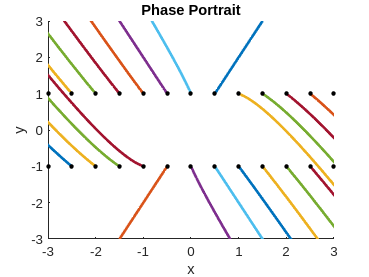

f = @(x,y) 3*x - y;
g = @(x,y) -4*x + 3*y;
figure();
set(gcf, 'Position', [100, 100, 800, 600]);
phasePortrait244(f, g, -3, 3, -3, 3, 0, 1.1, [-3:0.5:3, -3:0.5:3], [1*ones(1,13), -1*ones(1,13)]);

(b)

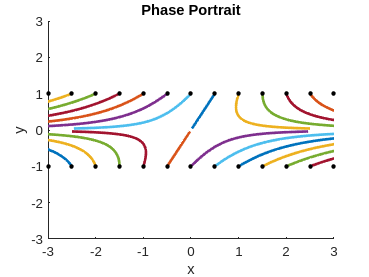

f = @(x,y) 2*x - 3*y;
g = @(x,y) -4*y;
figure();
set(gcf, 'Position', [100, 100, 800, 800]);
phasePortrait244(f, g, -3, 3, -3, 3, 0, 0.8, [-3:0.5:3, -3:0.5:3], [1*ones(1,13), -1*ones(1,13)]);

(c)

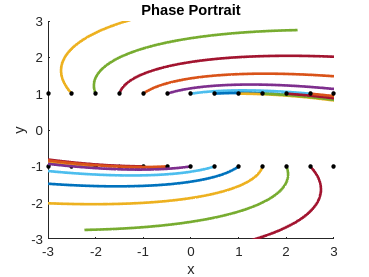

f = @(x,y) 3*x + 5*y;
g = @(x,y) -x + y;
figure();
set(gcf, 'Position', [100, 100, 800, 800]);
phasePortrait244(f, g, -3, 3, -3, 3, 0, 0.6, [-3:0.5:3, -3:0.5:3], [1*ones(1,13), -1*ones(1,13)]);

(d)

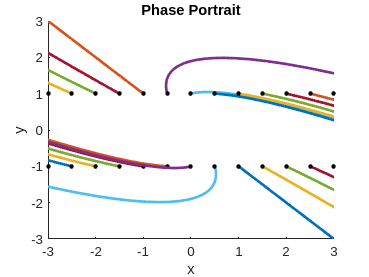

f = @(x,y) 7*x + 3*y;
g = @(x,y) -3*x + y;
figure();
set(gcf, 'Position', [100, 100, 800, 800]);
phasePortrait244(f, g, -3, 3, -3, 3, 0, 0.9, [-3:0.5:3, -3:0.5:3], [1*ones(1,13), -1*ones(1,13)]);

## 7.

(a) Point: (0,0)

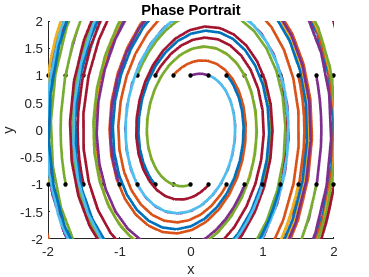

f = @(x,y) y;
g = @(x,y) -4*x + 0.5*y;
figure();
set(gcf, 'Position', [100, 100, 800, 600]);
phasePortrait244(f, g, -2, 2, -2, 2, 0, 10, [-3:0.25:3, -3:0.25:3], [1*ones(1,25), -1*ones(1,25)]);

(b) Point ($\pi/4$, 0)

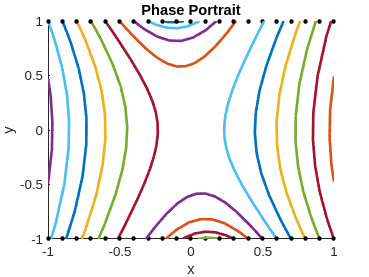

f = @(x,y) y;
g = @(x,y) 4*x + 0.5*y;
figure();
set(gcf, 'Position', [100, 100, 800, 600]);
phasePortrait244(f, g, -1, 1, -1, 1, 0, 10, [-3:0.1:3, -3:0.1:3], [1*ones(1,61), -1*ones(1,61)]);

Comment: 

These portraits do indeed show the behavior around the critical points (0,0) and (pi/4 , 0). As discussed below the plot in step 5, one can see this behavior in the "fuller" plot, where this converging critical point transitions to a diverging critical point in a cycle of pi/4.